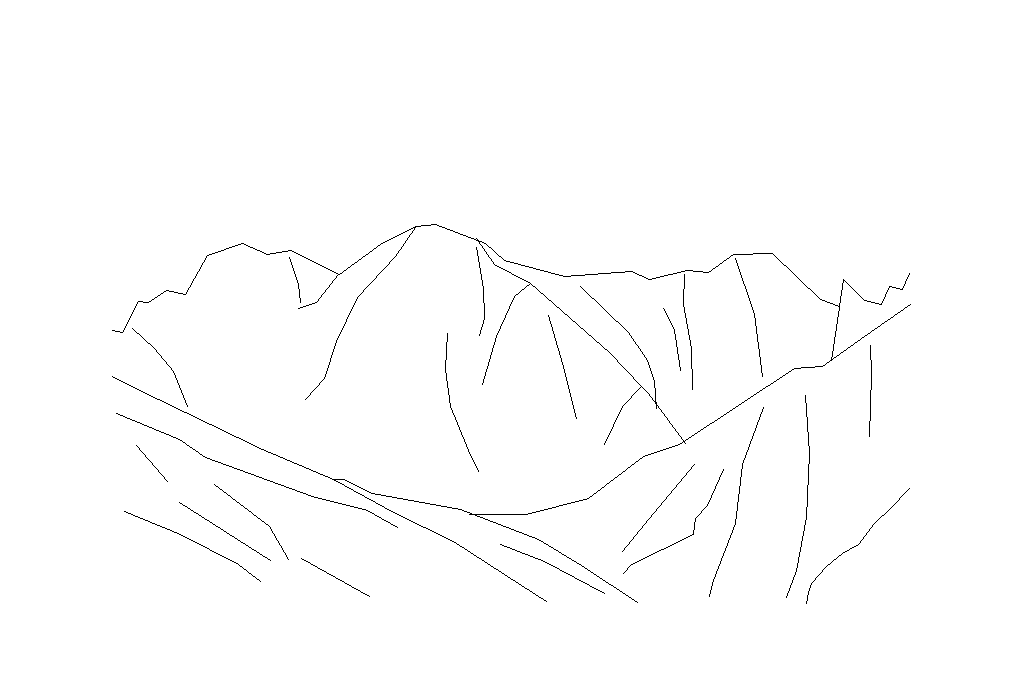

ans =    600   800     3


addpath(genpath('scripts'));
load('dataSets/TorontoScenes/mountains_vecLD.mat');
cute = vecLD(11);
imgLD = renderLinedrawing(cute);
figure;
imshow(imgLD);

MAT = computeMAT(imgLD,28);

MAT = struct with fields:
        skeleton: [600×800 logical]
    distance_map: [600×800 single]
             AOF: [600×800 double]


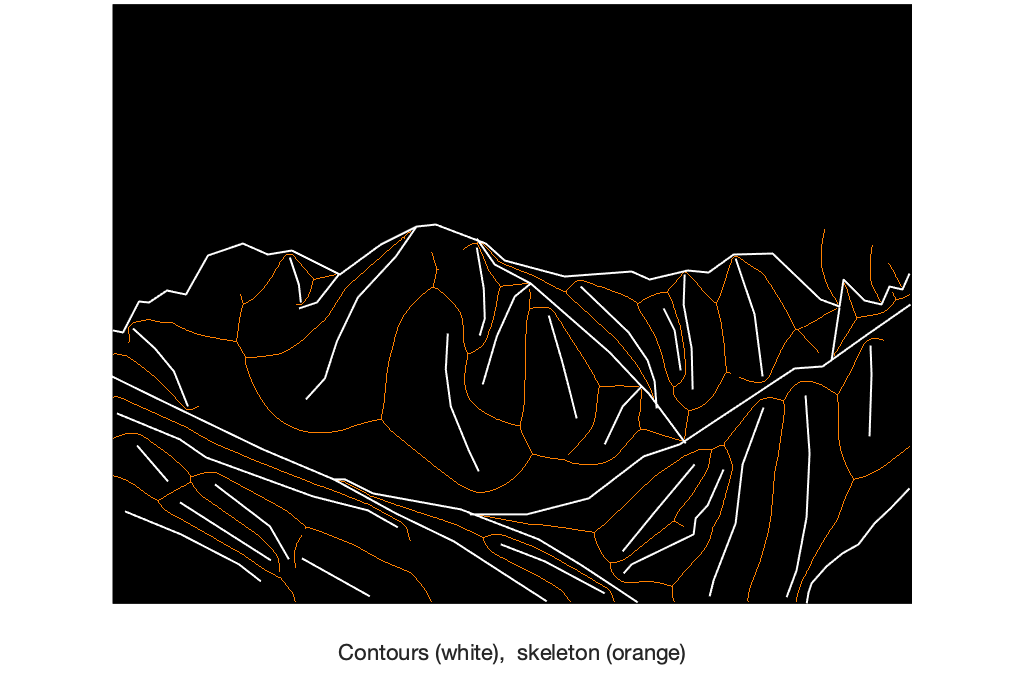

figure;
imshow(cat(3,MAT.skeleton,0.5*MAT.skeleton,zeros(size(MAT.skeleton))));
hold on;
drawLinedrawing(cute,'white',1)
% imshow(imoverlay(imcomplement(rgb2gray(imgLD)),MAT.skeleton,[1,0.5,0]))
xlabel('Contours (white),  skeleton (orange)')

figure;
imagesc(MAT.distance_map);
hold on;
drawLinedrawing(cute,'white',1)
c = colorbar;
c.Label.String = 'Distance to the closest contour'

c =   ColorBar (Distance to the closest contour) with properties:

    Location: 'eastoutside'
      Limits: [-1 270.6677]
    FontSize: 9
    Position: [0.8496 0.1661 0.0286 0.7022]
       Units: 'normalized'

  Show all properties


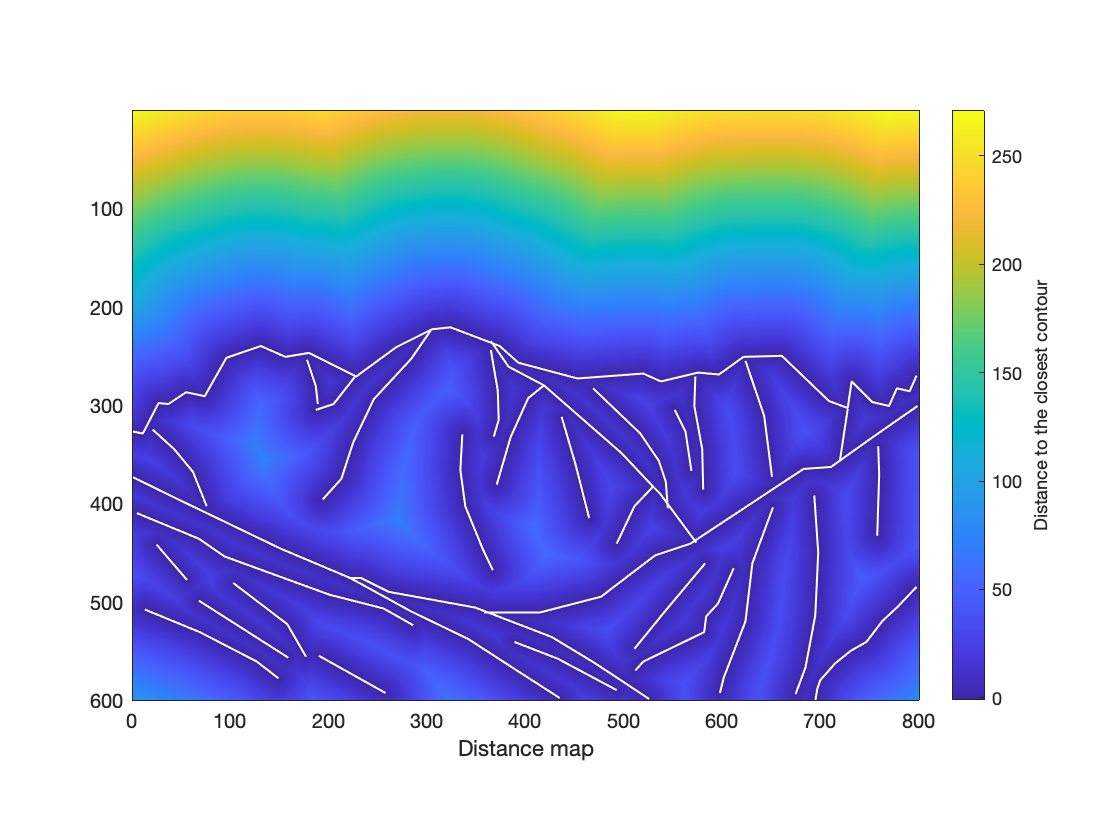

xlabel('Distance map')

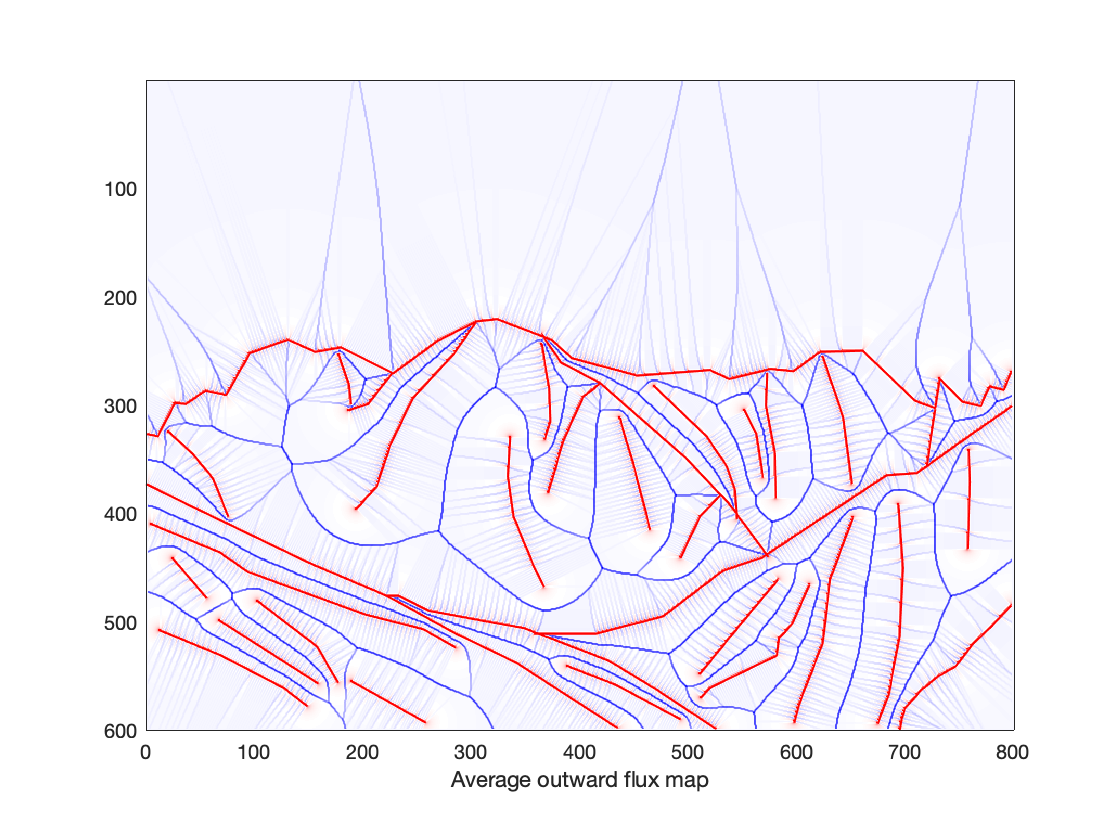

figure;
imagesc(-(MAT.AOF))
colormap redblue
hold on;
drawLinedrawing(cute,'red',1)
xlabel('Average outward flux map')